# Q1a

Write your own function to find the stabilizing solution to an algebraic Riccati equation. Your function should check the conditions for solution existence and provide meaningful error messages if no stabilizing solution exists. The function inputs should be the A, Q, and R matrices of the equation


$$A^T X+\textrm{XA}+\textrm{XRX}+Q=0$$


Use your function to find the solution to

$A=\left\lbrack \begin{array}{ccc}
-3 & 2 & 5\\
-2 & 1 & 6\\
4 & 5 & 6
\end{array}\right\rbrack$, $R=I_{3\textrm{x3}}$, $Q=\left\lbrack \begin{array}{ccc}
1 & 4 & 4\\
4 & 7 & 7\\
4 & 7 & 10
\end{array}\right\rbrack$

Show also the result of your function when A is scaled by 0.1.

A = [-3 2 5;-2 1 6;4 5 6];
R = eye(3);
Q = [1 4 4;4 7 7;4 7 10];
H = [A R;-Q -A'];
[V, J] = jordan(H)

V =    1.8105 + 0.0000i  -0.2759 + 0.0000i   0.6733 - 0.0000i  -0.7244 - 0.0000i  -1.1178 + 0.0000i   0.0219 - 0.0000i
  -3.2419 - 0.0000i   0.0368 - 0.0000i  -2.3268 + 0.0000i  -0.8485 + 0.0000i  -1.4310 - 0.0000i  -0.0122 + 0.0000i
   1.6014 + 0.0000i  -0.0717 + 0.0000i   1.1303 - 0.0000i   0.5645 - 0.0000i  -2.8295 + 0.0000i  -0.0652 - 0.0000i
   5.7639 + 0.0000i  -1.8880 + 0.0000i   0.3318 - 0.0000i   0.2336 - 0.0000i   2.7509 + 0.0000i   0.2024 - 0.0000i
  -6.0679 - 0.0000i   0.0210 - 0.0000i  -0.7239 + 0.0000i   0.1501 + 0.0000i   2.2121 - 0.0000i   0.5655 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


J =    1.0249 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   4.8764 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0249 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -4.8764 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   9.7555 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -9.7555 - 0.0000i


X_1 = [0.6733 -0.7244 0.0219; -2.3268 -0.8485 -0.0122; 1.1303 0.5645 -0.0652]; % only consider LHP(stable)
X_2 = [0.3318 0.2336 0.2024; -0.7239 0.1501 0.5655; 1 1 1];
X = X_2 * inv(X_1)

X =    -0.5828   -1.7548   -2.9717
   -1.7551   -4.3051   -8.4573
   -2.9719   -8.4565  -14.7533


X = are(A,-R,Q)

X =    -0.5831   -1.7561   -2.9740
   -1.7561   -4.3085   -8.4633
   -2.9740   -8.4633  -14.7651


A_scaled = 0.1 * [-3 2 5;-2 1 6;4 5 6];
H_s = [A_scaled R;-Q -A_scaled'];
[V_s, J_s] = jordan(H_s)

V_s =    8.2416 + 0.0000i  -0.0565 - 0.0957i   0.1352 + 0.1745i  -4.3804 + 0.0000i  -0.0565 + 0.0957i   0.1352 - 0.1745i
  -1.9374 + 0.0000i  -0.0591 - 0.1916i  -0.0709 + 0.9477i   2.0011 + 0.0000i  -0.0591 + 0.1916i  -0.0709 - 0.9477i
  -1.9243 + 0.0000i  -0.0658 - 0.2230i   0.0061 - 0.8944i   0.4691 + 0.0000i  -0.0658 + 0.2230i   0.0061 + 0.8944i
  -5.4862 - 0.0000i   0.4174 - 0.1090i  -0.1478 + 0.4645i  -6.8962 - 0.0000i   0.4174 + 0.1090i  -0.1478 - 0.4645i
   5.1848 + 0.0000i   0.8146 - 0.1068i  -1.0527 + 0.3958i   0.9024 + 0.0000i   0.8146 + 0.1068i  -1.0527 - 0.3958i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


J_s =   -1.1294 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 + 4.0730i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.1429i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.1294 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 4.0730i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 1.1429i


X_1_s = [V_s(1,1) V_s(1,2) V_s(1,6); V_s(2,1) V_s(2,2) V_s(2,6); V_s(3,1) V_s(3,2) V_s(3,6)]; % only consider LHP
X_2_s = [V_s(4,1) V_s(4,2) V_s(4,6); V_s(5,1) V_s(5,2) V_s(5,6); V_s(6,1) V_s(6,2) V_s(6,6)];
X_s = X_2_s * inv(X_1_s)

X_s =   -0.6116 + 0.4002i   0.4239 + 0.7734i  -0.1951 + 0.9353i
   0.4239 + 0.7734i  -0.2222 + 0.9230i  -0.6552 + 2.3829i
  -0.1951 + 0.9353i  -0.6552 + 2.3829i  -0.6957 + 1.6069i


% X_s = are(A_scaled,-R,Q) % No solution

# Q2a

(a) Consider the standard mixed sensitivity control configuration with plant model $P=\frac{s-10}{\left(s+1\right)\left(s+10\right)}$ and set $W_p =\frac{1}{s+0\ldotp 001}$, $W_u =\frac{s+2}{s+10}$ and $W_T$ empty. Design a controller that minimizes ${\left\|{\left\lbrack W_p S\;W_u \textrm{KS}\right\rbrack }^T \right\|}_2$Solve the same problem using H∞ synthesis and plot the step response of T for both designs on the same graph.

s = tf("s");
G = (s-10)/(s+1)/(s+10);
% state_space = ss(G);
% K_lqr = inv(R) * B' * X;
Wp = 1/(s+0.001);
Wu = (s+2)/(s+10);
systemnames = 'G Wp Wu'; %Block name only
inputvar = '[r;u]';
outputvar = '[Wp;Wu;r-G]'; %Strangely, the system outputs are just the name
input_to_G = '[u]';
input_to_Wp = '[r-G]';
input_to_Wu = '[u]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;
[K2,CL2,GAM2] = h2syn(P,1,1); 
S2 = inv(1+G*K2);
T2 = 1-S2;
norm_2 = norm([Wp*S2; Wu*K2*S2], 2)

norm_2 = 1.0627

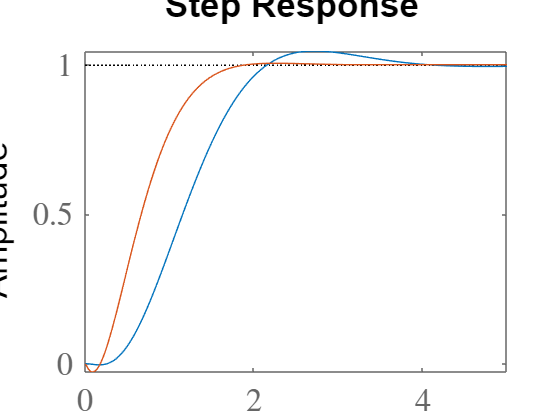

[Khinf,CL,GAM] = hinfsyn(P,1,1);
Tinf  = feedback(G*Khinf,1);
step(T2, Tinf)

% step(Tinf)

# Q2b

Consider the model matching control problem shown here:

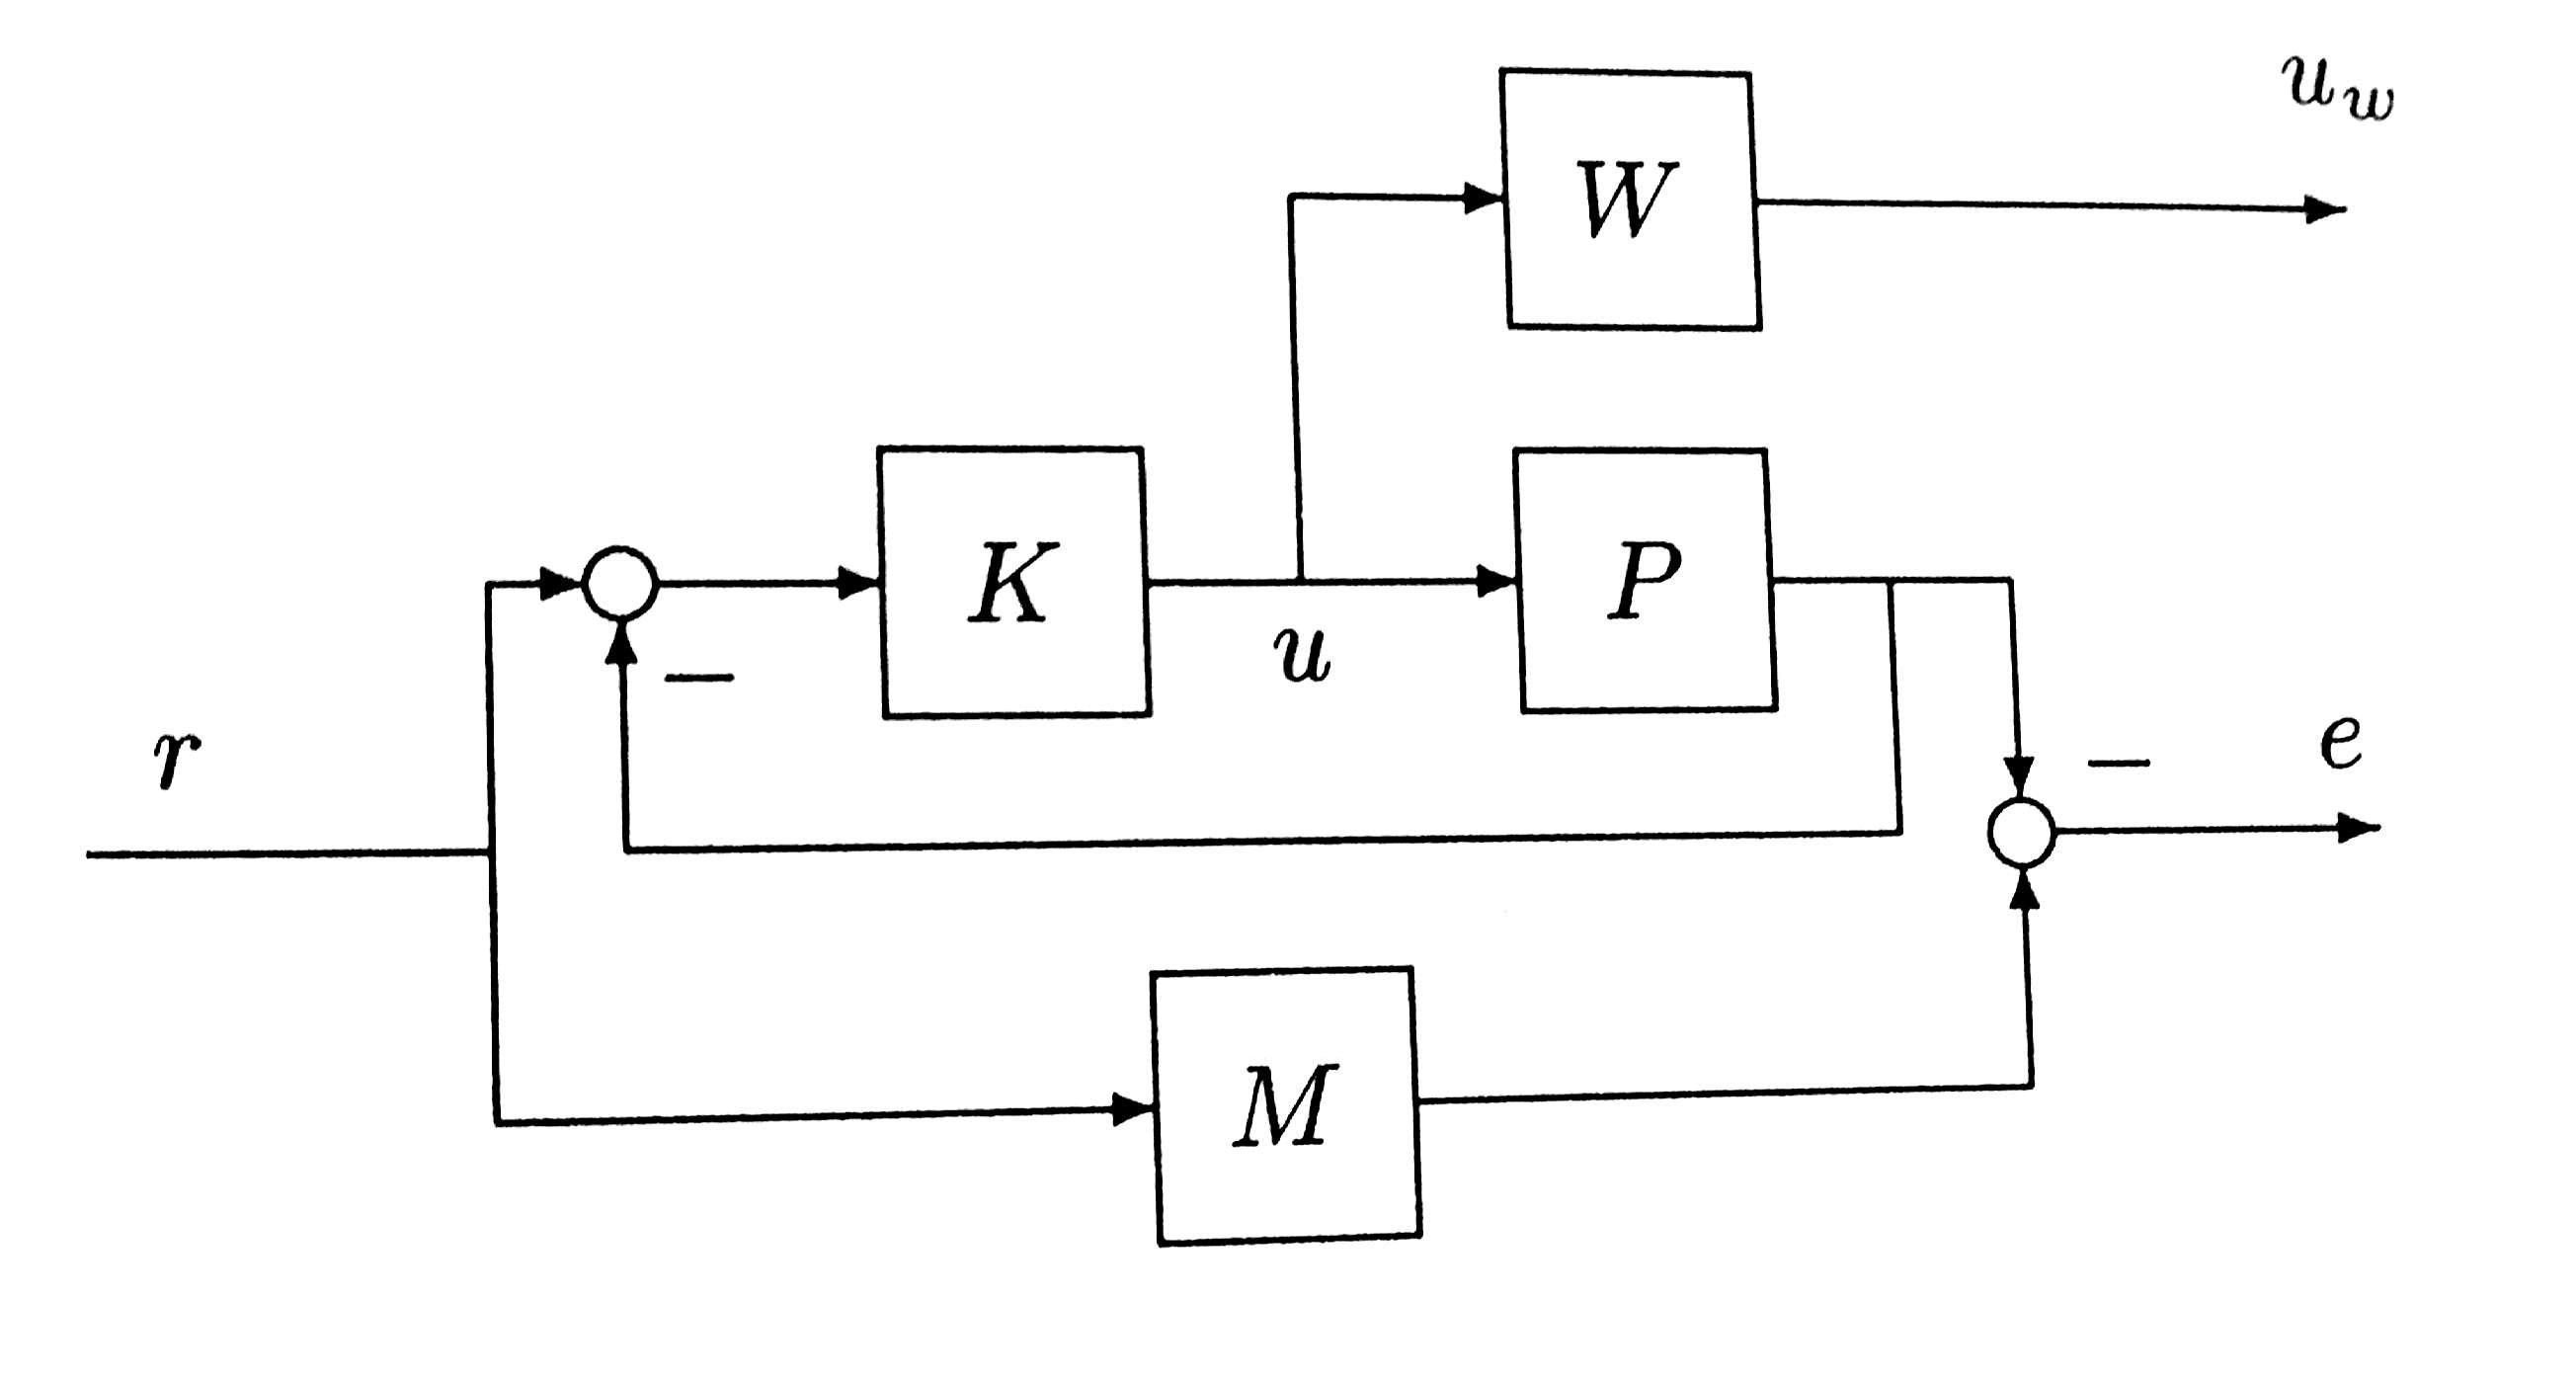

Setup and solve the H2 optimal control problem the minimizes uw and e for $M\left(s\right)=\frac{4}{s^2 +2s+4}$, $P\left(s\right)=\frac{10\left(s+2\right)}{{\left(s+1\right)}^3 }$, and$W\left(s\right)=\frac{0\ldotp 1\left(s+1\right)}{s+10}$. Plot the step response of the closed loop system on the same plot as the step response of M to demonstrate the performance of your model matcher.

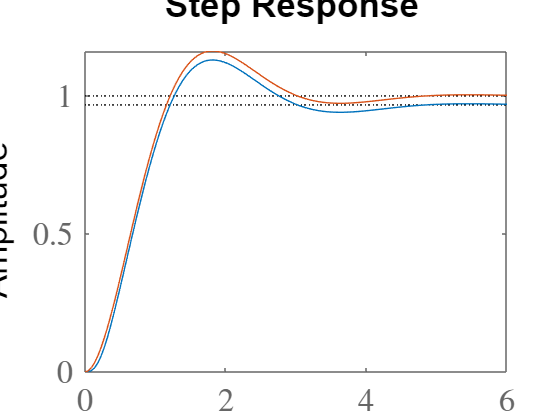

W = 0.1 * (s+1)/(s+10);
P = 10*(s+2)/(s+1)^3;
M = 4/(s^2+2*s+4);
systemnames = 'P M W'; %Block name only
inputvar = '[r;u]';
outputvar = '[W;M-P;r-P]'; %Strangely, the system outputs are just the name
input_to_P = '[u]';
input_to_M = '[r]';
input_to_W = '[u]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P2 = sysic;
[K2,CL2,GAM2] = h2syn(P2,1,1);
step(feedback(P*K2,1), M);

# Q3

Furata Pendulum Control

The Furata pendulum is a classical system that is both non-minimum phase and unstable when the pendulum is balanced upright.

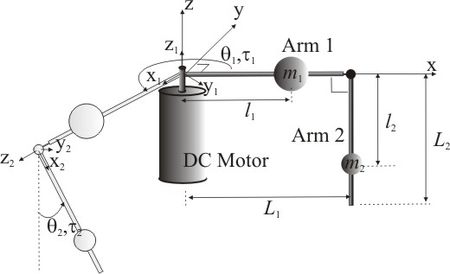

For a specific design the linearized model is given by


$$\begin{array}{l}
\overset{\ldotp }{x} =\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & 149\ldotp 3 & -0\ldotp 01 & 0\\
0 & 261\ldotp 6 & -0\ldotp 01 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
0\\
49\ldotp 73\\
49\ldotp 73
\end{array}\right\rbrack u\\
\\
y=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack 
\end{array}$$


(a) In terms of parameters and uncertainty, the file plant.m includes an uncertain linear model that includes 20% parametric uncertainty in the mass of the pendulum. Fit multiplicative output uncertainty weights to the uncertain plant. Plot the Bode plot of your plant with multiplicative uncertainty on top of the plant with parametric uncertainty to demonstrate the quality of your fit.

%% Motor
% Resistance
Rm = 8.4;
% Current-torque (N-m/A)
kt = 0.042;
% Back-emf constant (V-s/rad)
km = 0.042;
%
%% Rotary Arm
% Mass (kg)
Mr = 0.095;
% Total length (m)
Lr = 0.085;
% Moment of inertia about pivot (kg-m^2)
Jr = Mr*Lr^2/12;
% Equivalent Viscous Damping Coefficient (N-m-s/rad)
Dr = 0;
%
%% Pendulum Link
% Mass (kg)
Mp = ureal('M',0.024,'Percentage',20);
% Total length (m)
Lp = 0.129;
% Moment of inertia about pivot (kg-m^2)
Jp = Mp*Lp^2/12;
% Equivalent Viscous Damping Coefficient (N-m-s/rad)
Dp = 0;
% Gravity Constant
g = 9.81;

% State Space Representation
Jt = Jr*Jp + Mp*(Lp/2)^2*Jr + Jp*Mp*Lr^2;
A = [0 0 1 0;
     0 0 0 1;
     0 Mp^2*(Lp/2)^2*Lr*g/Jt -Dr*(Jp+Mp*(Lp/2)^2)/Jt -Mp*(Lp/2)*Lr*Dp/Jt;
     0 Mp*g*(Lp/2)*(Jr+Mp*Lr^2)/Jt -Mp*(Lp/2)*Lr*Dr/Jt -Dp*(Jr+Mp*Lr^2)/Jt];

B = [0; 0; (Jp+Mp*(Lp/2)^2)/Jt; Mp*(Lp/2)*Lr/Jt];
C = eye(2,4);  %Measure only the angles
D = zeros(2,1);

% Add actuator dynamics
B = kt * B / Rm;
A(3,3) = A(3,3) - kt*kt/Rm*B(3);
A(4,3) = A(4,3) - kt*kt/Rm*B(4);

% Load into state-space system
Gunc = ss(A,B,C,D); %2 outputs 1 input 
G = Gunc.NominalValue; %2 outputs 1 input 


Fit uncertainty plant

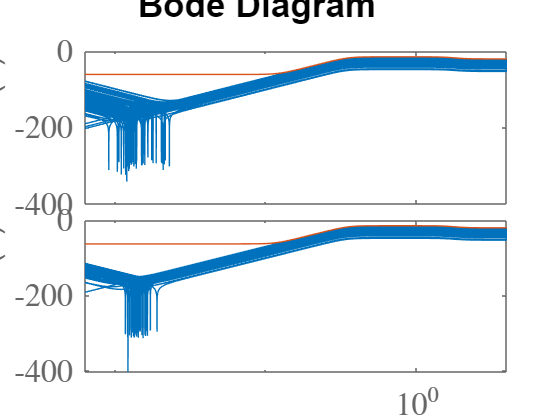

Gunc_samples = usample(Gunc,100);
[P11,info11] = ucover(Gunc_samples(1,1),G(1,1),2);
[P21,info21] = ucover(Gunc_samples(2,1),G(2,1),2);
G11 = (Gunc_samples(1,1)-G(1,1))/G(1,1);
G21 = (Gunc_samples(2,1)-G(2,1))/G(2,1);
% bodemag(P, G)
bodemag([G11;G21], [info11.W1;info21.W1])

# Q3b

(b) For unstable, non-minimum phase systems it is often difficult to know where to start with our weights on S. LQG control can be used to get a starting point from which we can add robustness. Build a Simulink model for the system that tracks a square wave reference of amplitude $\frac{\pi }{2}$ in motor angle while balancing the pendulum. Design an LQG controller that achieves “good” simulation performance.

QXU =  blkdiag(diag([100 100 10 10]),1);
QWV = blkdiag(10000*eye(4),1*eye(2));
reg = lqg(G,QXU,QWV);

# Q3c

(c) Using your final LQG design as your guide, develop a diagonal performance weight for the system. Design an H∞ optimal controller for the uncertain system using the uncertainty found in Part a. Iterate on the controller design, retuning a constant control weight to achieve good performance. For the final controller, plot the sensitivity function against the sensitivity function achieved by the LQG controller. 

NOTE1: The inverse of the sensitivity function is often unstable. You can use the *fitmagfrd* function to find stable approximations for the sensitivity weights if you choose to use the sensitivity function from Part b directly.

NOTE2: H∞ synthesis is generally unhappy about imaginary axis poles. You can move them by multiplying the appropriate transfer function by s/s+ϵ and being sure to take a minimal realization.

s = tf("s");
epl = 1e-6;
S_lqg = inv(eye(2) - G * reg);
range = logspace(-2,4);
Wp11 = fitmagfrd(frd(1/S_lqg(1,1), range),2);
Wp22 = fitmagfrd(frd(1/S_lqg(2,2), range),2);
Wp = blkdiag(Wp11, Wp22); 
WI = [info11.W1 0; 0 info21.W1];
Wu = 0.01;
[Khinf,CL,GAM] = mixsyn(G,Wp,Wu,WI);
G = G*s/(s+epl);
S_inf = minreal(inv(eye(2)-G * Khinf));

9 states removed.


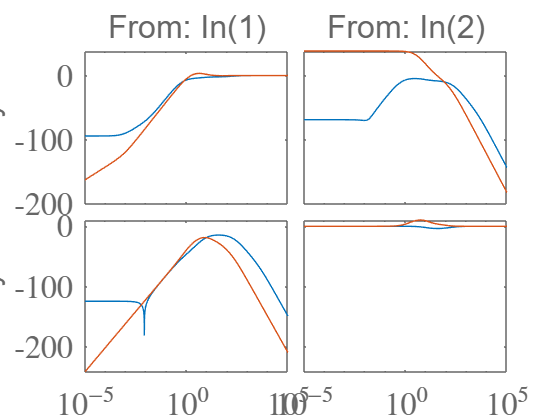

bodemag(S_inf, S_lqg);

# Q3d

(d) Test the robust stability of your LQG and H∞ designs and plot the uncertain sensitivity functions on top of each other. Has the H∞ design succeeded in adding robustness?

Sunc_lqg = inv(eye(2) + Gunc*reg);
[stabmarg,wcu] = robstab(Sunc_lqg);
mu_lqg = 1/stabmarg.LowerBound

mu_lqg = Inf

Sunc_inf = inv(eye(2) + Gunc*Khinf);
[stabmarg,wcu] = robstab(Sunc_inf);
mu_inf = 1/stabmarg.LowerBound

mu_inf = 0.4764

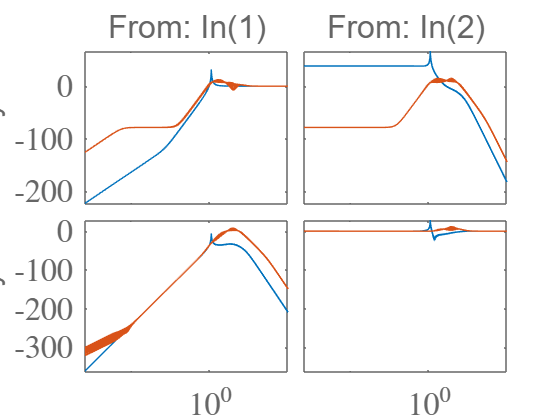

bodemag(Sunc_lqg, Sunc_inf);